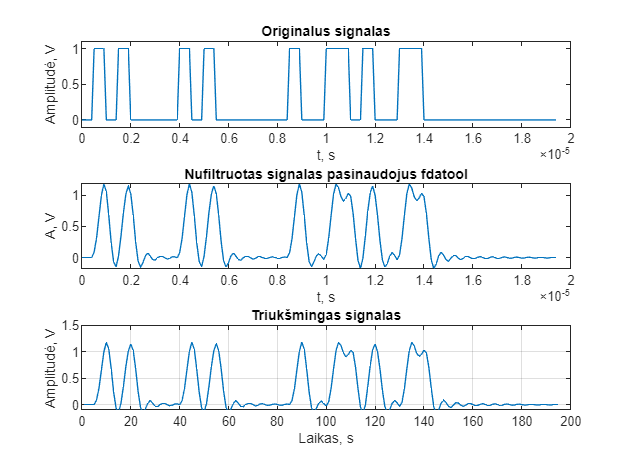

fdiskret = 10E6;
tdiskret = 1/fdiskret;
A = 1;

one = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret))];
zero = [zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];


preambule = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];
originalus = [zeros(1, 5), preambule, zeros(1, round(3E-6/tdiskret)), one, zero, one, one, zero, one, zeros(1, 50)];
%N = 4 * 1 / fsignal * fdiskret;
%n = 0:N-1;
%t = 0:1/fdiskret:1/fdiskret*(N-1);
%s = 2+ A * sin(2 * pi * fsignal * n / fdiskret);
N = length(originalus);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(3, 1, 1)
plot(t, originalus)
xlabel('t, s')
ylabel('Amplitudė, V')
title('Originalus signalas')
ylim([-0.1, 1.1])

%Filtro š
load 'FiltroKoef.mat'
nufiltruotas = filter(Hd, originalus);
subplot(3, 1, 2)
plot(t, nufiltruotas)
title("Nufiltruotas signalas pasinaudojus fdatool")
xlabel("t, s")
ylabel("A, V")


%Triuksmo generavimas
vid = 0;
std = 0.0;
triuksmas = vid + std*abs(randn(1, N));
triuksmasFiltruotas = filter(Hd, triuksmas);
triuksmingasSignalas = nufiltruotas + triuksmasFiltruotas;
subplot(3, 1, 3)
plot(triuksmingasSignalas)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
ylim([-0.1, 1.5])
grid on

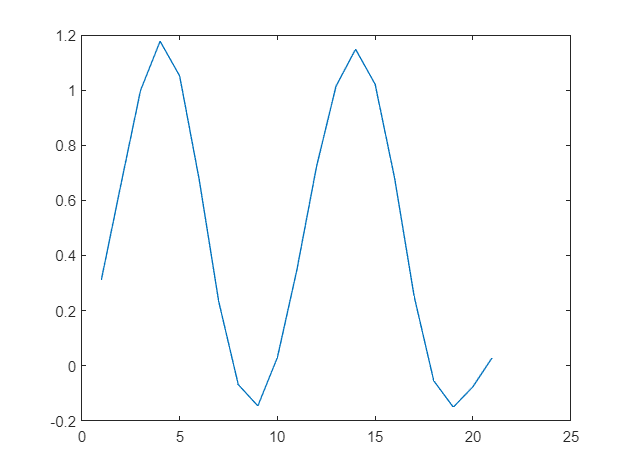

%Prafiltruojam ir testavimo duomenis
oneone = filter(Hd, [one, one, zeros(1, 15)]);
onezero = filter(Hd, [one, zero, zeros(1, 15)]);
zeroone = filter(Hd, [zero, one, zeros(1, 15)]);
zerozero = filter(Hd, [zero, zero, zeros(1, 15)]);

oneone = oneone(2:2+20);
onezero = onezero(2:2+20);
zeroone = zeroone(2:2+20);
zerozero = zerozero(2:2+20);

figure
plot(oneone)

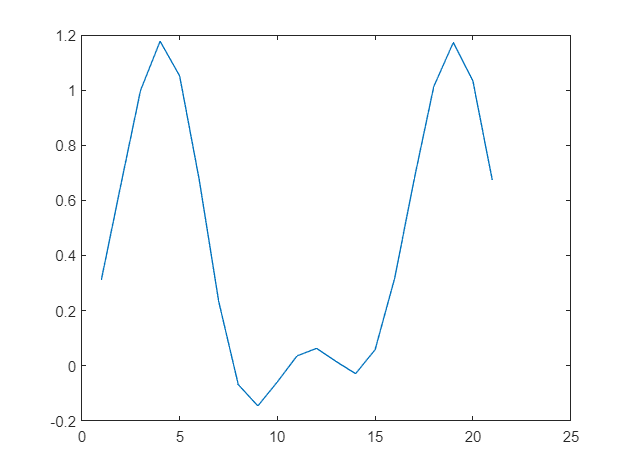

plot(onezero)


triuksmingasItamposVertemis = round(triuksmingasSignalas / 1.5*255); %1.5V Vref
for i = 1: length(triuksmingasItamposVertemis)
    if(triuksmingasItamposVertemis(i) > 255)
        triuksmingasItamposVertemis(i) = 255;
    elseif(triuksmingasItamposVertemis(i) < 0)
        triuksmingasItamposVertemis(i) = 0;
    end
end
preambuleItamposVertemis = preambule / 1.5*255;


%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(triuksmingasItamposVertemis)
    temp = dec2bin(triuksmingasItamposVertemis(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(preambuleItamposVertemis)
    temp = dec2bin(preambuleItamposVertemis(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(one)
    temp = dec2bin(one(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(zero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}
funkcijuFailas = fopen('Conv_func_data.mif','w');
duomenisIrasyti = [preambuleItamposVertemis, one, zero, zero, one, zero, zero, one, one]; %Praembule, one, zero

fprintf(funkcijuFailas, "WIDTH=8;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=UNS;\nCONTENT BEGIN \n", length(duomenisIrasyti));

for i = 1:length(duomenisIrasyti)
    %temp = dec2bin(duomenisIrasyti(i), 8);
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %i;\n',i-1, duomenisIrasyti(i));
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);

testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(triuksmingasItamposVertemis)
    if(triuksmingasItamposVertemis(i) > 255)
        temp = dec2bin(255, 8);
    elseif(triuksmingasItamposVertemis(i) < 0)
        temp = dec2bin(0, 8);
    else
        temp = dec2bin(triuksmingasItamposVertemis(i), 8);
    end
    
    fprintf(testVoltage,'%s\n',temp);
end


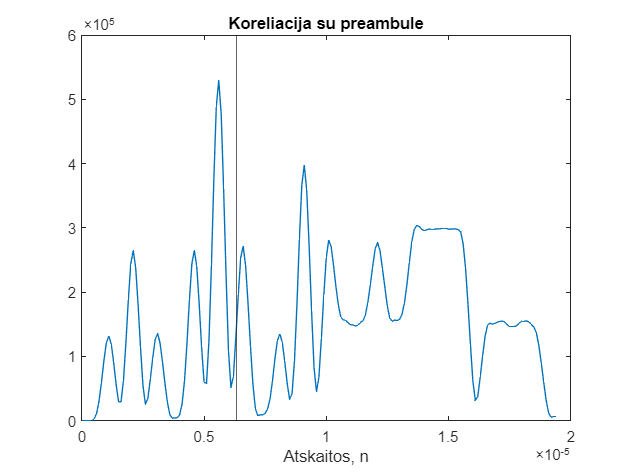


konvoliucija = conv(triuksmingasItamposVertemis, preambuleItamposVertemis);
figure
plot(t, konvoliucija(1:length(triuksmingasItamposVertemis)))
xline(6.34E-6);
title('Koreliacija su preambule')
xlabel('Atskaitos, n')

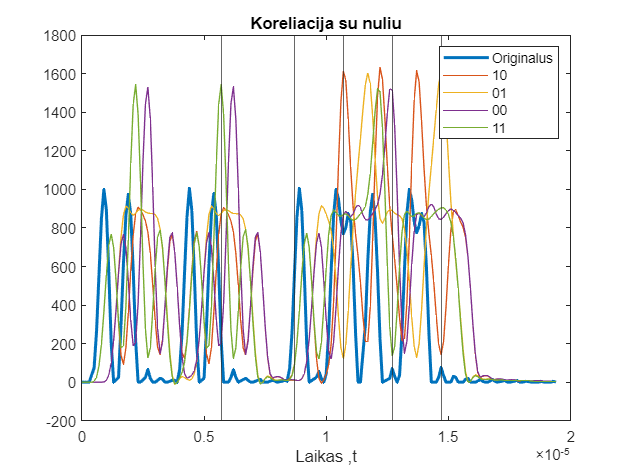


plot(t, triuksmingasItamposVertemis*5, 'LineWidth',2)
hold on
%konvoliucija1 = conv(triuksmingasItamposVertemis, one);
%plot(t, konvoliucija1(1:length(triuksmingasItamposVertemis)))
title('Koreliacija su vienetu')
xlabel('Atskaitos, n')

%konvoliucija2 = conv(triuksmingasItamposVertemis, zero);
%plot(t, konvoliucija2(1:length(triuksmingasItamposVertemis)))
title('Koreliacija su nuliu')
xlabel('Laikas ,t')
konvoliucija3 = conv(triuksmingasItamposVertemis, onezero);
plot(t, konvoliucija3(1:length(triuksmingasItamposVertemis)))

konvoliucija4 = conv(triuksmingasItamposVertemis, zeroone);
plot(t, konvoliucija4(1:length(triuksmingasItamposVertemis)))

konvoliucija5 = conv(triuksmingasItamposVertemis, zerozero);
plot(t, konvoliucija5(1:length(triuksmingasItamposVertemis)))

konvoliucija6 = conv(triuksmingasItamposVertemis, oneone);
plot(t, konvoliucija6(1:length(triuksmingasItamposVertemis)))

xline(5.7E-6);
xline(5.7E-6+3E-6);
xline(5.7E-6+3E-6+2E-6);
xline(5.7E-6+3E-6+4E-6);
xline(5.7E-6+3E-6+6E-6);

%xline(117/fdiskret, 'color','green');
%xline(138/fdiskret, 'color','green');
%xline(159/fdiskret, 'color','green');

legend("Originalus", "10", "01", "00", "11")

hold off

[amplitude, vieta] = max(konvoliucija) %15 uzvelina

amplitude = 529550

vieta = 57

vietaLaike = vieta / fdiskret %1.34us uzvelina

vietaLaike = 5.7000e-06

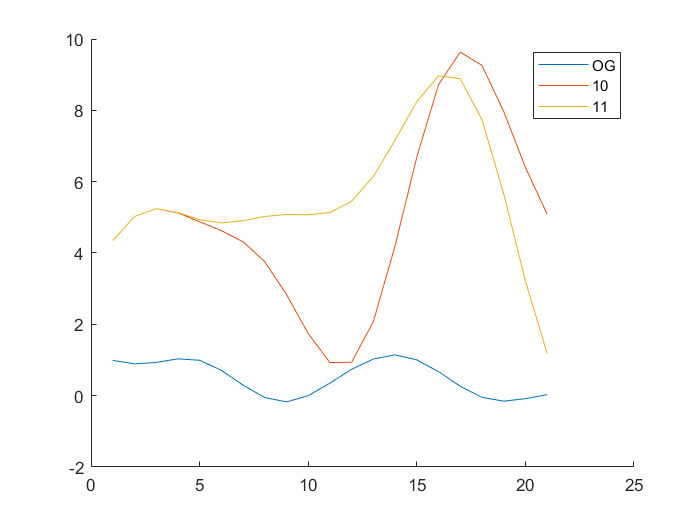

%Testavimas

arrayus = [zeros(1, 30), zero, one, one, zero, zeros(1, 30)];
arrayus = filter(Hd, arrayus);

vienvien = conv(arrayus, oneone);
nulnul = conv(arrayus, zerozero);
viennul = conv(arrayus, onezero);

figure
hold on
plot(arrayus(42:62))
plot(viennul(42:62))
plot(vienvien(42:62))
legend("OG", "10", "11");

hold off

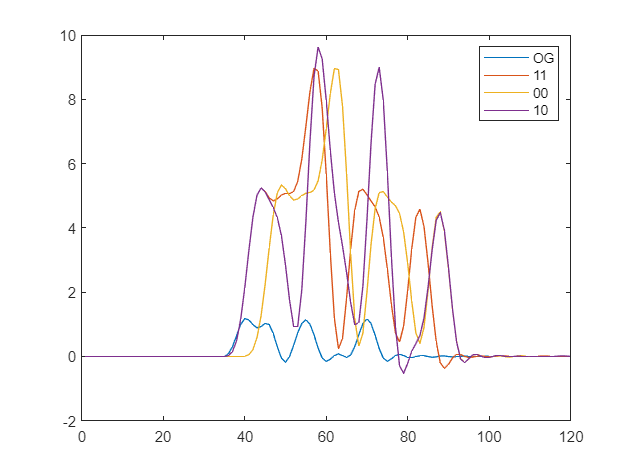


figure
plot(arrayus)
hold on
plot(vienvien)
plot(nulnul)
plot(viennul)
legend("OG", "11", "00", "10")
hold off

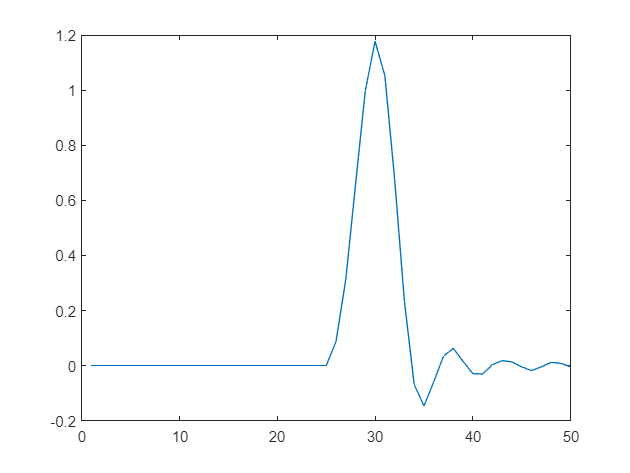

zeroFilt = filter(Hd, [zeros(1, 20), zero, zeros(1, 20)]);
plot(zeroFilt)

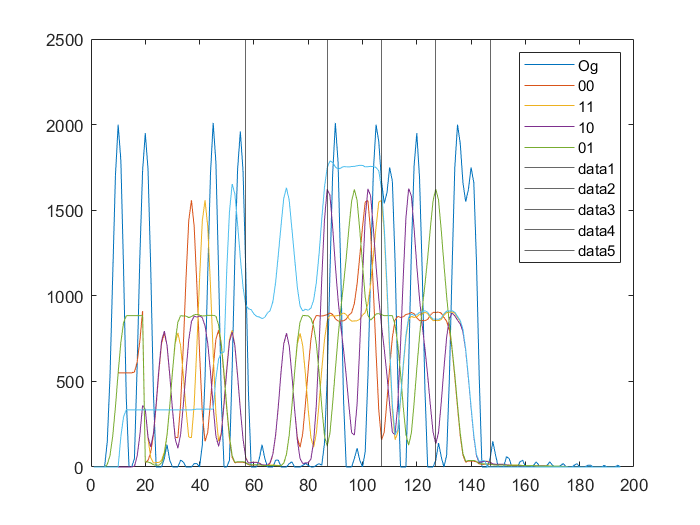


n11 = GenerateConv(triuksmingasItamposVertemis, [one, one]);
n00 = GenerateConv(triuksmingasItamposVertemis, [zero, zero]);
n01 = GenerateConv(triuksmingasItamposVertemis, [zero, one]);
n10 = GenerateConv(triuksmingasItamposVertemis, [one, zero]);
np = GenerateConv(triuksmingasItamposVertemis, preambule);

plot(triuksmingasItamposVertemis*10)
hold on
plot(n00)
plot(n11)
plot(n10)
plot(n01)
plot(np)

legend("Og", "00", "11", "10", "01")

xline((5.7E-6)*fdiskret);
xline((5.7E-6+3E-6)*fdiskret);
xline((5.7E-6+3E-6+2E-6)*fdiskret);
xline((5.7E-6+3E-6+4E-6)*fdiskret);
xline((5.7E-6+3E-6+6E-6)*fdiskret);
hold off

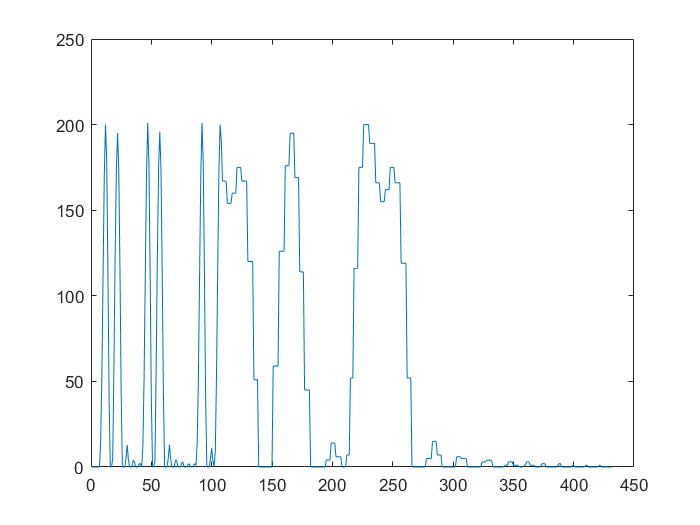

%IMIMAS IS MODELSIMO
msfile = fopen('modelsimData.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 Inf]);

% time +4 arrIndex  adcout 00 01 10 11

for i = 1:length(msdata(4, :))
    msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
plot(msdata(4, :))

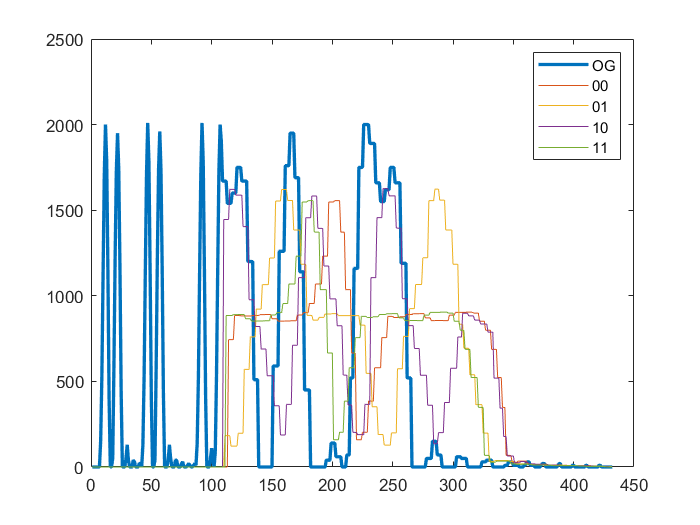


figure
plot(msdata(4, :)*10, 'LineWidth',2)
hold on
plot(msdata(5, :))
plot(msdata(6, :))
plot(msdata(7, :))
plot(msdata(8, :))
legend("OG", "00", "01", "10", "11")

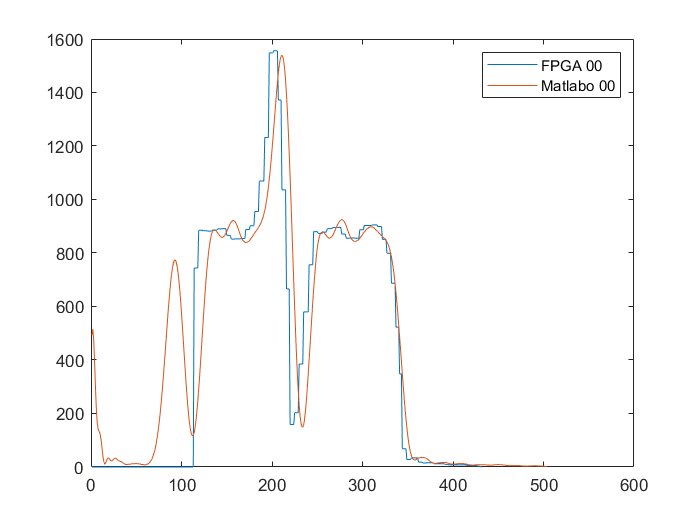


figure

plot(msdata(5, :))
hold on
plot(resample(konvoliucija5(75:200), 4, 1))
legend( "FPGA 00", "Matlabo 00")
hold off

function y = GenerateConv(a, b)
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
end

